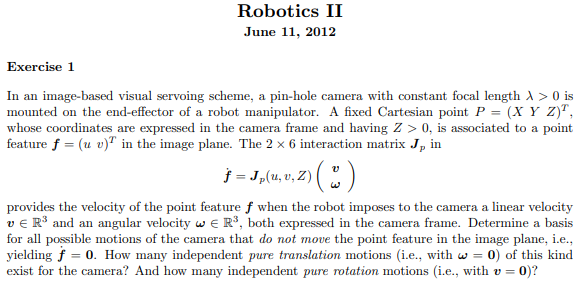

% clc;clear;
% [J_camera,velocities,V,OMEGA,u,v,Z,lambda]=gen_interaction_matrix(1)

J_camera = 1×1 cell array
    {2×6 sym}


J_camera = 1×1 cell array
    {2×6 sym}


velocities = 1×1 cell array
    {1×1 struct}


$$V = \left(\begin{array}{c} V_{1}\\ V_{2}\\ V_{3} \end{array}\right)$$

$$OMEGA = \left(\begin{array}{c} \Omega_{1}\\ \Omega_{2}\\ \Omega_{3} \end{array}\right)$$

$$u = u_{1}$$

$$v = v_{1}$$

$$Z = Z_{1}$$

$$lambda = \lambda$$

% J_b=(J_camera{1})%+J_camera{2})/2 %divided by 2= gometric barycenter

$$J\_b = \left(\begin{array}{cccccc} -\frac{\lambda }{Z_{1}} & 0 & \frac{u_{1}}{Z_{1}} & \frac{u_{1}\,v_{1}}{\lambda } & -\lambda -\frac{{u_{1}}^{2}}{\lambda } & v_{1}\\ 0 & -\frac{\lambda }{Z_{1}} & \frac{v_{1}}{Z_{1}} & \lambda +\frac{{v_{1}}^{2}}{\lambda } & -\frac{u_{1}\,v_{1}}{\lambda } & -u_{1} \end{array}\right)$$

% % J_b=(J_camera{1}+J_camera{2}+J_camera{3})/3
% OMEGA=[0,0,0]' 

OMEGA =      0
     0
     0


% % V=[0,0,0]' 
% vel_=J_b*[V;OMEGA]

$$vel\_ = \left(\begin{array}{c} \frac{V_{3}\,u_{1}}{Z_{1}}-\frac{V_{1}\,\lambda }{Z_{1}}\\ \frac{V_{3}\,v_{1}}{Z_{1}}-\frac{V_{2}\,\lambda }{Z_{1}} \end{array}\right)$$

% null(vel_')

$$ans = \left(\begin{array}{c} -\frac{V_{2}\,\lambda -V_{3}\,v_{1}}{V_{1}\,\lambda -V_{3}\,u_{1}}\\ 1 \end{array}\right)$$

% resn=(simplify(null(J_b))) %one ofthis solutions works well also

$$resn = \begin{array}{l} \left(\begin{array}{cccc} \frac{u_{1}}{\lambda } & \sigma_{1} & -\frac{Z_{1}\,\left(\lambda^{2}+{u_{1}}^{2}\right)}{\lambda^{2}} & \frac{Z_{1}\,v_{1}}{\lambda }\\ \frac{v_{1}}{\lambda } & \frac{Z_{1}\,\left(\lambda^{2}+{v_{1}}^{2}\right)}{\lambda^{2}} & -\sigma_{1} & -\frac{Z_{1}\,u_{1}}{\lambda }\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{Z_{1}\,u_{1}\,v_{1}}{\lambda^{2}} \end{array}$$

% res1=simplify(J_b*resn(:,1))

$$res1 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

% % J_b(1,1)
% % J_b(1,3)
% % simplify(J_b(1,3)/J_b(1,1))

% % res=solve([vel_==0;V~=0],[V])

% % % res.Omega_1
% % res.V_1
% % res.V_2
% % res.V_3
% 

% lambda*resn(:,1) %purely (v,0)'

$$ans = \left(\begin{array}{c} u_{1}\\ v_{1}\\ \lambda \\ 0\\ 0\\ 0 \end{array}\right)$$

% simplify(expand(u*resn(:,2)+v*resn(:,3)+lambda*resn(:,4))) %purely (,omega)'

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ u_{1}\\ v_{1}\\ \lambda \end{array}\right)$$